# Medical Image Processing - Final Project

## **Authors: **

- **Javier Sanguino Alcolado**

- **Max Witwer **

- **Braden Schweer**

- **Melanie Werzi**

- **Tobias Haider**

## Preparation

### Load the scripts

addpath("script/NIFTI_reader");
addpath("script/segmentation");
addpath("script/segmentation/plot");

### Import images

ct_lungs_noise = load_nii('data/CT_lungs_noise.nii');
ct_lungs = load_nii('data/CT_lungs.nii');
ct = load_nii('data/CT.nii');
pet = load_nii('data/PET.nii');

## Image Segmentation

### Exercise 1: Segment the images with Otsu

ct_segmentation = otsu_segmentation(ct.img);
pet_segmentation = otsu_segmentation(pet.img);

### Exercise 2: Plot the segmentation result

#### CT

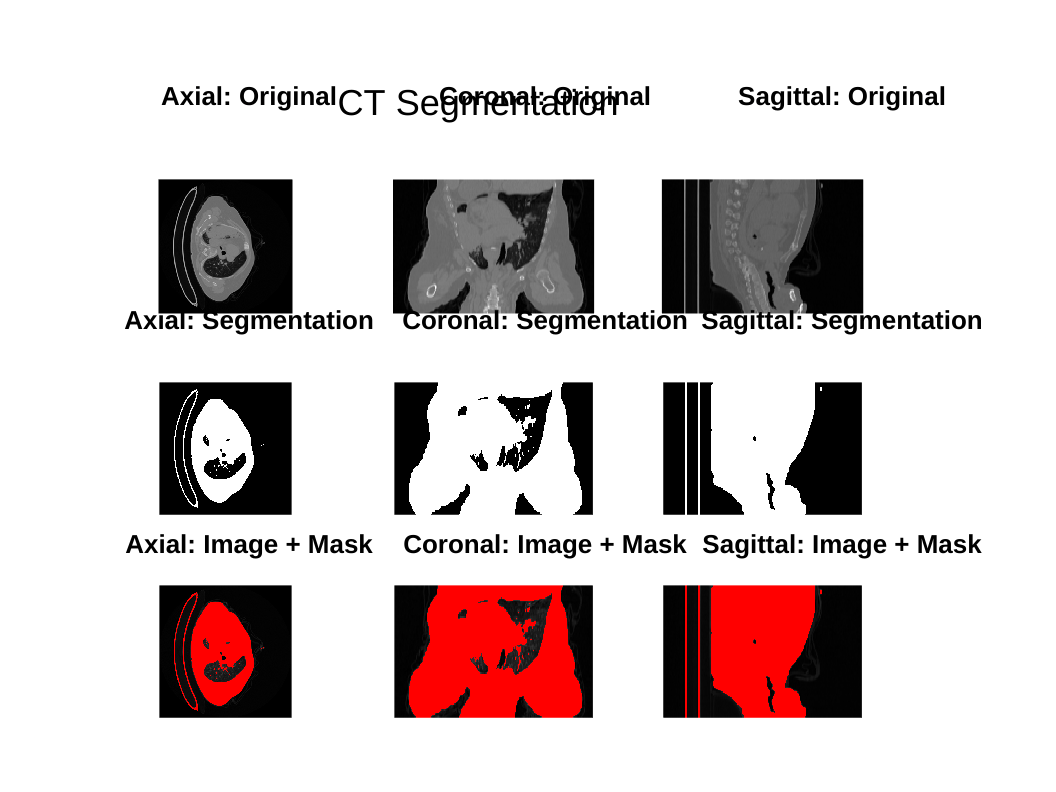

plot_segmentation(ct.img, ct_segmentation, ct.hdr.dime.pixdim(2:4));
sgtitle("CT Segmentation");

#### PET

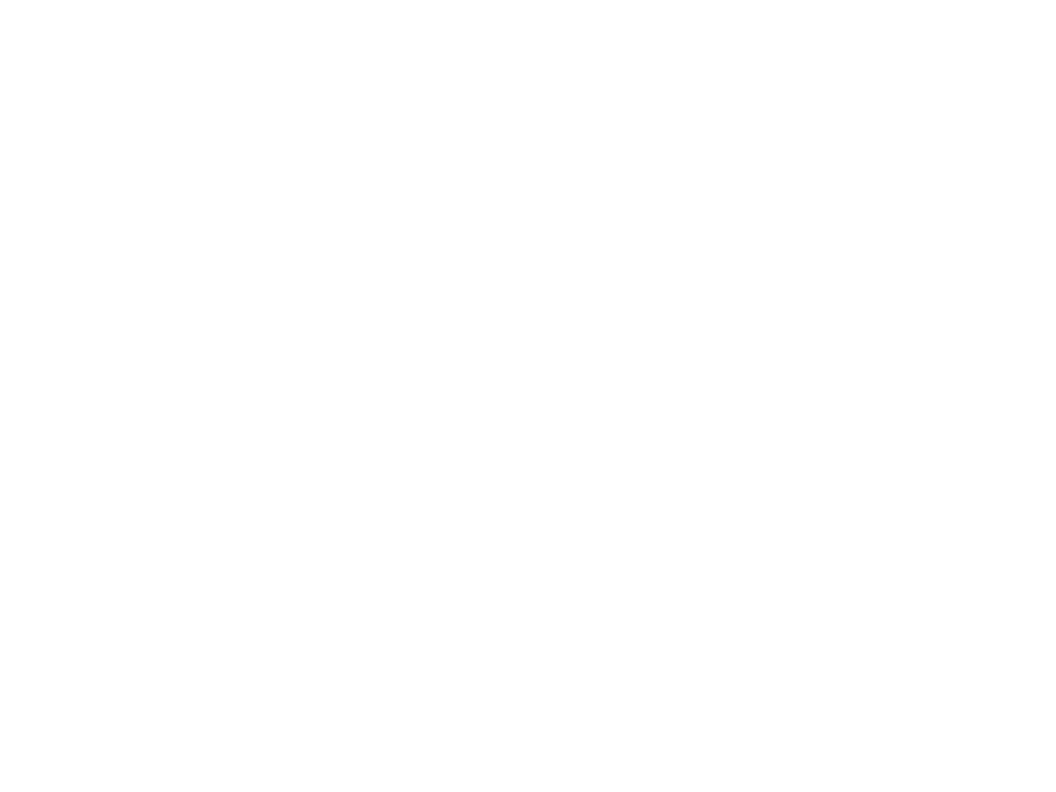

plot_segmentation(pet.img, pet_segmentation, pet.hdr.dime.pixdim(2:4));
sgtitle("PET Segmentation");

## Morphological Filters

## Quantification